# Aula 9 - Laboratório de Controle - 2021/1

# Projeto do controlador avanço-atraso para o motor CC

## Nome: Yuri Rissi Negri

turma=5 ;
I=8 ;
Tempo=3.5;

M=[5 9 3 4 1 2 12 7 11 10 8 6
     2 4 5 11 10 1 9 8 7 3 6 12
     9 1 12 8 5 11 6 3 2 4 10 7
     7 6 9 2 11 5 8 4 3 10 12 1
    12 9 3 11 7 8 5 2 10 1 6 4]';

wn=M(I,turma);

arquivo='aula9_R2018.slx';  

load dados.mat
i=wn*50;
ind=(i-20):(i+35);
y1=y1(ind);
u1=u1(ind);
t1=t1(ind);
Ref=mean(y1(end-10:end));
u0=mean(u1(1:10));

## Atividade 0 - Estimação da FT

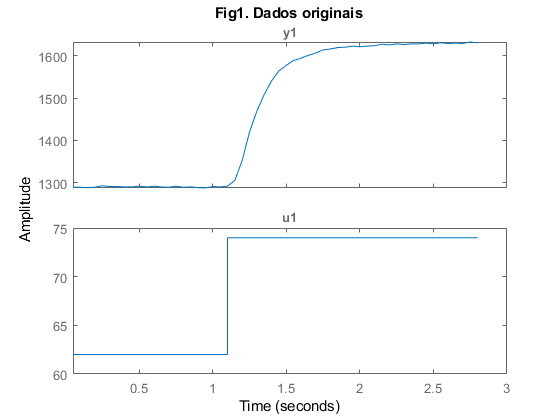

dat=iddata(y1,u1,Ts);
dat_1=iddata(y1-y1(1),u1-u1(1),Ts);
figure
plot(dat);title('Fig1. Dados originais');

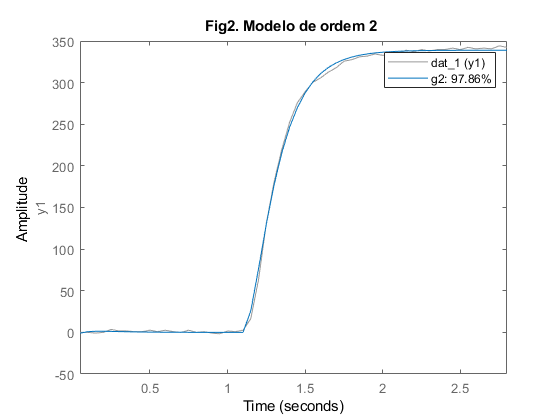

g2=tfest(dat_1,2,0);
g2=tf(g2.Numerator,g2.Denominator);
K=freqresp(g2,0);
compare(dat_1,g2);title('Fig2. Modelo de ordem 2 ');

s=stepinfo(g2);
ts_ma=s.SettlingTime

ts_ma = 0.7316

Ts=0.01;

## Atividade 1 - Obtenção das especificações em frequência a partir do tempo

Na atividade 3 do relatório 8, o melhor PID gerou um bom valor de UP e ts. Como no relatório 7, um modelo de referência é gerado com UP e ts, para obter as especificações em frequência.

UPe=2;
tse=0.18;
a=log(UPe/100);
zeta=sqrt(a^2/(pi^2+a^2));
wn=4/(tse*zeta);
gma=tf(wn^2,[1 2*zeta*wn 0]);
m=tf(wn^2,[1 2*zeta*wn wn^2]);
[~,MFe]=margin(gma);
BWe=bandwidth(m);
Mpe=20*log10(max(bode(m)));
UP=UPe;ts=tse;MF=MFe;BW=BWe;Mp=Mpe;
Tipo={'Especificacoes'};
Tabela1=table(Tipo,UP,ts,MF,BW,Mp)

Tabela1 = 1×6 table
          Tipo          UP     ts       MF        BW          Mp    
    ________________    __    ____    ______    ______    __________

    'Especificacoes'    2     0.18    68.998    25.569    -0.0023143


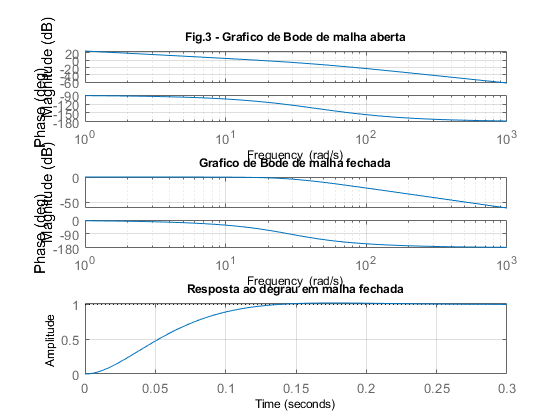

subplot(3,1,1);bode(gma);title('Fig.3 - Grafico de Bode de malha aberta');grid
subplot(3,1,2);bode(m);title('Grafico de Bode de malha fechada');grid
subplot(3,1,3);step(m);title('Resposta ao degrau em malha fechada');grid

1.1 Como garantir o atendimento das especificações no tempo usando as especificações em frequência?

    Como podemos observar no código acima, encontramos a função de transferência na forma padrão para o nossas especificações de UP e ts, dessa forma é traçado o gráfico de Bode e obtém-se a margem de fase e os outros parâmetros para malha fechada em frequência para essas mesmas especificações.

    Assim, partindo da nossa forma de onda g2 que como visto nos laboratórios anteriores é uma aproximação da resposta ao degrau real do nosso sistema, podemos analisar no domínio da frequência e variar esses parâmetros, no caso a margem de fase, a fim de se obter um controlador que se aproxime das especificações. Logo, podemos variar a margem de fase do nosso sistema inserindo controladores de atraso e/ou avanço a fim de se obter os UP e ts desejados.

## Atividade 2 - Projeto do controlador Atraso

O gráfico de Bode de malha aberta mostrado na Figura 4 já tem o efeito do ganho para atender o erro em regime.

2.1 Qual deve ser o aumento  da margem de fase para alcançar a margem de fase especificada? 

    Observando o diagrama de bode na figura 4, podemos analisar a curva de K*g2 que é de nosso interesse para a síntese do controlador avanço-atraso, e podemos perceber que a margem de fase é de aproximadamente 12º. Assim para nossa margem de fase especificada obtida a partir dos valores de UP e ts do nosso controlador PID, obtivemos em torno de 69º, portanto devemos ter um aumento de cerca de 57º. 

    Podemos perceber também, que a inserção do ganho K no nosso sistema, gerou uma diminuição da margem de fase, onde antes nossa curva g2 apresentava uma margem de fase de aproximadamente 22º, o que resultava em um aumento de 47º para obter a mf especificada.       

Erro_reg=0.01; % Erro percentual de 1%
K1=(1/Erro_reg-1)/K

K1 = 3.5050

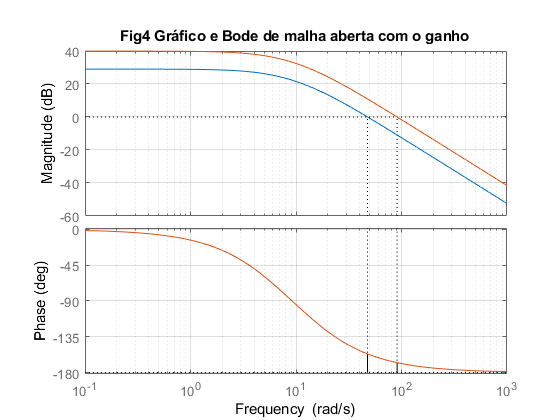

figure
margin(g2);hold on;
margin(K1*g2); grid; title('Fig4 Gráfico e Bode de malha aberta com o ganho'); hold off

2.2 Escolha um valor de MFd para o projeto do controlador atraso de fase, explicando seu efeito no diagrama de Bode (Fig.5) e na resposta ao degrau (Fig.6)

    Tendo em mente que nossa margem de fase especificada foi de aproximadamente de 69º, não devemos tomar valores maiores que esse. Ao observar a figura 5 referente a resposta em relação ao controlador atraso, nota-se que conforme aumentávamos MFd obtivemos respostas muito lentas, enquanto que para valores pequenos de MFd resultava em respostas mais oscilatórias. 

    Contudo, assim como na alocação do zero em um controlador PI na síntese de um PID, nossa escolha de MFd deve ser escolhido observando a melhor resposta no controlador final. Assim obtivemos que o MFd do controlador atraso que nos gerava uma melhor resposta no controlador avanço é de 45º. 

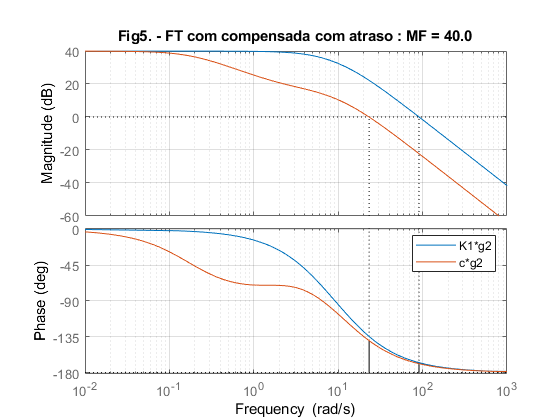

MFd=45;
[c,at]=projat(g2,K1,MFd);

margin(K1*g2);hold on;margin(c*g2);legend('K1*g2','c*g2');grid; hold off
[~,MF1]=margin(c*g2);
str = sprintf('Fig5. - FT com compensada com atraso : MF = %.1f',floor(MF1));
title(str);

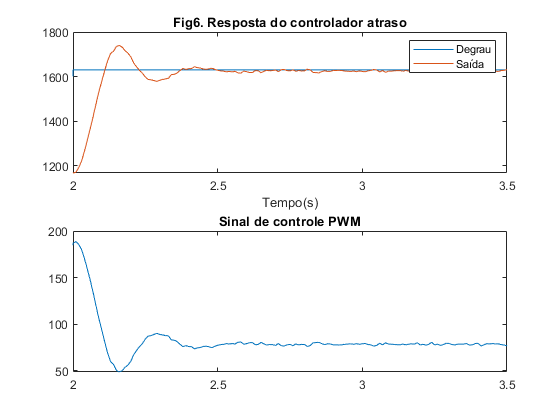

Ts=0.01; 
a=at(1);
T=at(2);
Nc=[a*T 1];
Dc=[T 1];

[Y,t]=simula_slx(arquivo,Tempo);
subplot(2,1,1);plot(t,Y(:,[1,3]));legend('Degrau','Saída');xlabel('Tempo(s)');
title('Fig6. Resposta do controlador atraso');
xlim([2 Tempo]);
subplot(2,1,2);plot(t,Y(:,2));title('Sinal de controle PWM');
xlim([2 Tempo]);


[erro1,UP1,SettlingTime1,iae,G2] = desempenho(Y(:,2:3),t,Ref,2);
m1=feedback(c*g2,1);
[mag,~,w]=bode(m1);
mag=20*log10(squeeze(mag));
BW1=bandwidth(m1);Mp1=20*log10(max(bode(m1)));
UP=[UPe;UP1];ts=[tse;SettlingTime1];MF=[MFe;MF1];BW=[BWe;BW1];Mp=[Mpe;Mp1];
Tipo={'Especificado';'Atraso'};
Tabela2=table(Tipo,UP,ts,MF,BW,Mp)

Tabela2 = 2×6 table
         Tipo           UP        ts        MF        BW          Mp    
    ______________    ______    ______    ______    ______    __________

    'Especificado'         2      0.18    68.998    25.569    -0.0023143
    'Atraso'          23.954    0.3562    40.161    36.603        3.2655


2.3 Verifique as melhorias conseguidas em MF, BW e Mp com o controlador avanço, analisando a tabela 2.

        Temos que BW e Mp são parâmetros em malha fechada no domínio da frequência relacionados com os parâmetros no domínio do tempo ts e UP respectivamente. Assim, podemos perceber ao analisar a tabela 2 referente ao controlador atraso que obtivemos valores maiores de BW e Mp, e consequentemente, maiores valores de estabelecimento e sobressinal em comparação ao especificado. Contudo, como foi dito, podemos pensar no controlador atraso como um controlador PI, onde a inserção de um controlador PD ajusta esses parâmetros, e a inserção do controlador avanço fará o mesmo sobre o controlador atraso, uma vez que nesse último estamos preocupados em encontrar o melhor valor de MFd. Assim, quando inserimos o controlador avanço, podemos perceber que haverá uma melhora significativa nesses parâmetros

        Em relação a MF, podemos perceber que nosso melhor MFd não atinge nossa margem de fase especificada. Essa diferença será adicionada pelo controlador avanço, pelo parâmetro "fi" definido na próxima etapa, que resultará em algo próximo a nosso resultado esperado nas especificações.

2.4 Qual o efeito de aumentar MFd sobre UP e ts ?

    Pode-se perceber que o aumento do MFd nos gerava menores valores sobressinal (UP), e até certo ponto, menores valores de tempo de estabelecimento (ts) no controlador atraso. Porém, devemos analisar também esse efeito na resposta do controlador avanço-atraso, onde a partir de uma certa MFd, tínhamos respostas muito lentas.

## Atividade 3 - Projeto do controlador Avanço

Escolha a fase fi a adicionar a MF e projetar o controlador avanço.

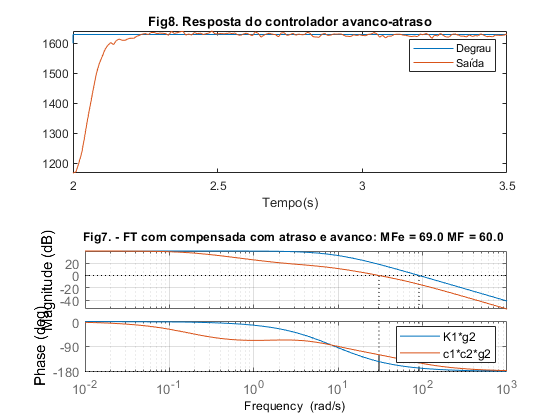

fi=29;
c1=c;
[c2,at]=projav(c1*g2,1,fi);
a=at(1);
T=at(2);
Nc=conv(Nc,[a*T 1]);
Dc=conv(Dc,[T 1]);

margin(K1*g2);hold on;margin(c1*c2*g2);legend('K1*g2','c1*c2*g2');grid; hold off
m2=feedback(c1*c2*g2,1);BW2=bandwidth(m2);MP2=20*log10(max(bode(m2)));
[~,MF2]=margin(c1*c2*g2);
str = sprintf('Fig7. - FT com compensada com atraso e avanco: MFe = %.1f MF = %.1f ',MFe,floor(MF2));
title(str);

[Y,t]=simula_slx(arquivo,Tempo);
subplot(2,1,1);plot(t,Y(:,[1,3]));legend('Degrau','Saída');xlabel('Tempo(s)');
title('Fig8. Resposta do controlador avanco-atraso');
xlim([2 Tempo]);

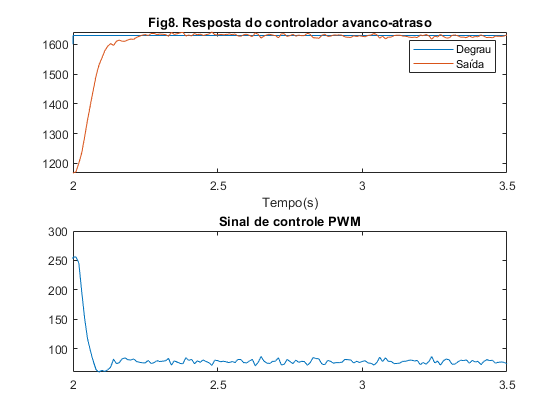

subplot(2,1,2);plot(t,Y(:,2));title('Sinal de controle PWM');
xlim([2 Tempo]);

3.1 Explique como escolher MFd e fi para atender as especificações. 

   Durante a análise do MFd no controlador atraso, pode-se perceber que ao aumentarmos o MFd tínhamos uma diminuição da velocidade da nossa resposta, onde para valores próximos a margem de fase especificada obtinhamos sistemas muito lentos e inviáveis no controlador avanço-atraso e para baixos valores de MFd obtivemos respostas com muito sobressinal no avanço-atraso.

    Já a escolha de "fi" foi definida como a diferença 69º e a margem de fase obtido na síntese do controlador atraso (obtido na tabela 2), ou seja, a fase que deveríamos inserir para se obter a margem de fase especificada. Dessa forma, foi se variando MFd em valores intermediários e o "fi" respectivo, a fim de se obter a melhor resposta.

[erro2,UP2,SettlingTime2] = desempenho(Y(:,2:3),t,Ref,2);
UP=[UPe;UP1;UP2];ts=[tse;SettlingTime1;SettlingTime2];MF=[MFe;MF1;MF2];BW=[BWe;BW1;BW2];Mp=[Mpe;Mp1;MP2];
Tipo={'Especificacoes';'Atraso';'Avanco-atraso'};
Erro=[100*Erro_reg;erro1;erro2];
Tabela3=table(Tipo,UP,ts,MF,BW,Mp,Erro)

Tabela3 = 3×7 table
          Tipo            UP        ts        MF        BW          Mp         Erro  
    ________________    ______    ______    ______    ______    __________    _______

    'Especificacoes'         2      0.18    68.998    25.569    -0.0023143          1
    'Atraso'            23.954    0.3562    40.161    36.603        3.2655    0.27694
    'Avanco-atraso'          0    0.1569    60.478    48.055       0.19477    0.20846


3.2 Comentar atendimento das especificações em frequência, com valores dos gráficos e da Tabela 3.

    Ao observar a tabela 3 e a figura 8, podemos ver que conseguimos atender as especificações, atingindo os parâmetros de sobressinal e tempo de estabelecimento ainda menores que o previsto, sendo nulo o UP e ts de aproximadamente 0.157

   Por fim, pode-se observar que os parâmetros Mp e MF apesar de alguma diferença se aproximaram bem das nossas especificações. O que mais sofreu variação foi o valor de BW, que apresentou ser quase o dobro.

3.3 Compare o projeto do PID com o do avano-atraso em relação a: a) erro em regime b) Dificuldades para fazer o projeto em duas etapas (PI depois PD ou atraso e depois avanço) c) Uso de especificações no tempo ou frequência

          Quando comparamos o erro em regime do controlador PID com avanço-atraso, é fácil perceber a superioridade do controlador PID para esse aspecto. O controlador PID aumenta o tipo do do nosso sistema como visto no último laboratório, o que leva a um erro igual a zero para uma resposta com entrada em degrau, que é o nosso caso. Já o controlador avanço-atraso apresenta um erro dado por aproximadamente 0.21.

        No que diz respeito a dificuldades na realização do projeto, pode-se perceber que a síntese do controlador avanço-atraso é mais simples e direta de ser realizada. Tivemos que encontrar somente o parâmetro MFd, uma vez que "fi" estava relacionado com o primeiro, onde já tínhamos uma MF especificada, enquanto que no PID tivemos que fazer uma análise mais minuciosa em torno dos zeros para se obter a melhor resposta possível. Contudo, pudemos perceber durante essas variações para a escolha que no geral, o controlador PID continua nos dando um maior grau de liberdade e precisão sobre os parâmetros da resposta desejada, de forma a se adequar melhor ao sistema dependendo apenas do projetista.

    Em relação às especificações no tempo ou frequência, o controlador PID se torna mais intuitivo uma vez que estamos projetando parâmetros no tempo variando os mesmo também no tempo. No controlador avanço-atraso analisamos na frequência para então se obter uma resposta no tempo, o que às vezes pode dificultar a visualização do efeito de um parâmetro na frequência sobre o tempo.

datetime('now')

ans = datetime
   18-Aug-2021 18:34:52


pwd

ans = 'C:\Users\asus1\Desktop\Aula9'